# Generate the Dynamics of the Three-Link 2D Biped

This function calculates the dynamics of the three-link biped, that is, it generates the mass matrix, M, the Coriolis Matrix C, the gravity Matrix G as well as the control matrix B:


$$M(q) \ddot q + C(q, \dot q) \dot q + G(q) = B u$$


Note that you first would need to complete and run the generate_kinematics.mlx. 

syms m1 m2 m3 g;
syms ddq1 ddq2 ddq3;

% T1, T2, T3: kinetic energies of m1, m2, m3
T1 = m1*(dx1^2+dz1^2)/2

$$T1 = \frac{m_{1}\,\left(\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{4}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{4}\right)}{2}$$

T2 = m2*(dx2^2+dz2^2)/2

$$T2 = \frac{m_{2}\,\left({\left({\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)}{2}\right)}^{2}\right)}{2}$$

T3 = m3*(dx3^2+dz3^2)/2

$$T3 = \frac{m_{3}\,\left({\left({\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\cos\left(q_{3}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\sin\left(q_{3}\right)}{2}\right)}^{2}\right)}{2}$$


% V1, V2, V3: potential energies of m1, m2, m3
V1 = m1*g*z1;
V2 = m2*g*z2;
V3 = m3*g*z3;

T = T1 + T2 + T3; % total kinetic energy 
V = V1 + V2 + V3; % total potential energy 

T = simplify(T, 'steps', 50)

$$T = \frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{8}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{3}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}\,m_{3}}{8}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$

V = simplify(V, 'steps', 50)

$$V = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}\right)+g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}\right)+\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}$$


L = T - V % Lagrangian

$$L = \frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{8}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{3}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}\,m_{3}}{8}-g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}\right)-g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}\right)-\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$

We use dLdqi for $\frac{\partial L}{\partial q_i}$ and  dLddqi for $\frac{\partial L}{\partial \dot q_i}$. 

dLdq1 = diff(L, q1);
dLdq2 = diff(L, q2);
dLdq3 = diff(L, q3);

dLddq1 = simplify(diff(L, dq1))

$$dLddq1 = \frac{{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{1}}{4}+{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{2}+{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{3}-\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$

dLddq2 = simplify(diff(L, dq2))

$$dLddq2 = \frac{l_{2}\,m_{2}\,\left({\mathrm{dq}}_{2}\,l_{2}-2\,{\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)}{4}$$

dLddq3 = simplify(diff(L, dq3))

$$dLddq3 = \frac{l_{3}\,m_{3}\,\left({\mathrm{dq}}_{3}\,l_{3}+2\,{\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{3}\right)\right)}{4}$$


dLddq1_dt = simplify(diff(dLddq1, q1) * dq1 + diff(dLddq1, q2) * dq2 + diff(dLddq1, q3) * dq3 + ...
    diff(dLddq1, dq1) * ddq1 + diff(dLddq1, dq2) * ddq2 + diff(dLddq1, dq3) * ddq3)

$$dLddq1\_dt = {\mathrm{dq}}_{1}\,\left(\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\right)+{\mathrm{ddq}}_{1}\,\left(\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}\right)-\frac{{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{ddq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}-\frac{{{\mathrm{dq}}_{2}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{3}}^{2}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$

dLddq2_dt = simplify(diff(dLddq2, q1) * dq1 + diff(dLddq2, q2) * dq2 + diff(dLddq2, q3) * dq3 + ...
    diff(dLddq2, dq1) * ddq1 + diff(dLddq2, dq2) * ddq2 + diff(dLddq2, dq3) * ddq3)

$$dLddq2\_dt = \frac{l_{2}\,m_{2}\,\left(2\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}-2\,{\mathrm{dq}}_{2}\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}+{\mathrm{ddq}}_{2}\,l_{2}-2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)}{4}$$

dLddq3_dt = simplify(diff(dLddq3, q1) * dq1 + diff(dLddq3, q2) * dq2 + diff(dLddq3, q3) * dq3 + ...
    diff(dLddq3, dq1) * ddq1 + diff(dLddq3, dq2) * ddq2 + diff(dLddq3, dq3) * ddq3)

$$dLddq3\_dt = \frac{l_{3}\,m_{3}\,\left(-2\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{{\mathrm{dq}}_{1}}^{2}+2\,{\mathrm{dq}}_{3}\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{\mathrm{dq}}_{1}+{\mathrm{ddq}}_{3}\,l_{3}+2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{3}\right)\right)}{4}$$

## Lagrange equations of motion

 Recall: 


$$\frac{d}{dt}(\frac{\partial L}{\partial \dot q_i}) - \frac{\partial L}{\partial q_i} = 0$$


Eq1 = dLddq1_dt - dLdq1

$$Eq1 = {\mathrm{dq}}_{1}\,\left(\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\right)+{\mathrm{ddq}}_{1}\,\left(\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}\right)-\frac{g\,l_{1}\,m_{1}\,\sin\left(q_{1}\right)}{2}-g\,l_{1}\,m_{2}\,\sin\left(q_{1}\right)-g\,l_{1}\,m_{3}\,\sin\left(q_{1}\right)-\frac{{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{ddq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}-\frac{{{\mathrm{dq}}_{2}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{3}}^{2}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$

Eq2 = dLddq2_dt - dLdq2

$$Eq2 = \frac{l_{2}\,m_{2}\,\left(2\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}-2\,{\mathrm{dq}}_{2}\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}+{\mathrm{ddq}}_{2}\,l_{2}-2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)}{4}+\frac{g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}$$

Eq3 = dLddq3_dt - dLdq3

$$Eq3 = \frac{l_{3}\,m_{3}\,\left(-2\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{{\mathrm{dq}}_{1}}^{2}+2\,{\mathrm{dq}}_{3}\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{\mathrm{dq}}_{1}+{\mathrm{ddq}}_{3}\,l_{3}+2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{3}\right)\right)}{4}-\frac{g\,l_{3}\,m_{3}\,\sin\left(q_{3}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$

Calculate the matrices M, C, G in the equations of motion:


$$M(q) \ddot q + C(q, \dot q) \dot q + G(q) = 0$$


Recall how you did this in assignment 1. 

G(1, 1) = subs(Eq1, {dq1,dq2,dq3,ddq1,ddq2,ddq3}, {0,0,0,0,0,0}); % use subs as in assignment 1
G(2, 1) = subs(Eq2, {dq1,dq2,dq3,ddq1,ddq2,ddq3}, {0,0,0,0,0,0});
G(3, 1) = subs(Eq3, {dq1,dq2,dq3,ddq1,ddq2,ddq3}, {0,0,0,0,0,0});

M(1, 1) = subs(simplify((Eq1 - G(1,1))/ddq1), {dq1,dq2,dq3,ddq2,ddq3}, {0,0,0,0,0});
M(1, 2) = subs(simplify((Eq1 - G(1,1))/ddq2), {dq1,dq2,dq3,ddq1,ddq3}, {0,0,0,0,0});
M(1, 3) = subs(simplify((Eq1 - G(1,1))/ddq3), {dq1,dq2,dq3,ddq1,ddq2}, {0,0,0,0,0});
M(2, 1) = subs(simplify((Eq2 - G(2,1))/ddq1), {dq1,dq2,dq3,ddq2,ddq3}, {0,0,0,0,0});
M(2, 2) = subs(simplify((Eq2 - G(2,1))/ddq2), {dq1,dq2,dq3,ddq1,ddq3}, {0,0,0,0,0});
M(2, 3) = subs(simplify((Eq2 - G(2,1))/ddq3), {dq1,dq2,dq3,ddq1,ddq2}, {0,0,0,0,0});
M(3, 1) = subs(simplify((Eq3 - G(3,1))/ddq1), {dq1,dq2,dq3,ddq2,ddq3}, {0,0,0,0,0});
M(3, 2) = subs(simplify((Eq3 - G(3,1))/ddq2), {dq1,dq2,dq3,ddq1,ddq3}, {0,0,0,0,0});
M(3, 3) = subs(simplify((Eq3 - G(3,1))/ddq3), {dq1,dq2,dq3,ddq1,ddq2}, {0,0,0,0,0});

C(1, 1) = subs(simplify((Eq1 - G(1,1))/dq1), {dq2,dq3,ddq1,ddq2,ddq3}, [0,0,0,0,0]);
C(1, 2) = subs(simplify((Eq1 - G(1,1))/dq2), {dq1,dq3,ddq1,ddq2,ddq3}, {0,0,0,0,0});
C(1, 3) = subs(simplify((Eq1 - G(1,1))/dq3), {dq1,dq2,ddq1,ddq2,ddq3}, {0,0,0,0,0});
C(2, 1) = subs(simplify((Eq2 - G(2,1))/dq1), {dq2,dq3,ddq1,ddq2,ddq3}, {0,0,0,0,0});
C(2, 2) = subs(simplify((Eq2 - G(2,1))/dq2), {dq1,dq3,ddq1,ddq2,ddq3}, {0,0,0,0,0});
C(2, 3) = subs(simplify((Eq2 - G(2,1))/dq3), {dq1,dq2,ddq1,ddq2,ddq3}, {0,0,0,0,0});
C(3, 1) = subs(simplify((Eq3 - G(3,1))/dq1), {dq2,dq3,ddq1,ddq2,ddq3}, {0,0,0,0,0});
C(3, 2) = subs(simplify((Eq3 - G(3,1))/dq2), {dq1,dq3,ddq1,ddq2,ddq3}, {0,0,0,0,0});
C(3, 3) = subs(simplify((Eq3 - G(3,1))/dq3), {dq1,dq2,ddq1,ddq2,ddq3}, {0,0,0,0,0});

G = simplify(G, 'steps', 50)

$$G = \left(\begin{array}{c} -\frac{g\,l_{1}\,\sin\left(q_{1}\right)\,\left(m_{1}+2\,m_{2}+2\,m_{3}\right)}{2}\\ \frac{g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}\\ -\frac{g\,l_{3}\,m_{3}\,\sin\left(q_{3}\right)}{2} \end{array}\right)$$

M = simplify(M) % simplify M

$$M = \begin{array}{l} \left(\begin{array}{ccc} \frac{{l_{1}}^{2}\,\left(m_{1}+4\,m_{2}+4\,m_{3}\right)}{4} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & \frac{{l_{2}}^{2}\,m_{2}}{4} & 0\\ \sigma_{2} & 0 & \frac{{l_{3}}^{2}\,m_{3}}{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}\\ \sigma_{2}=\frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2} \end{array}$$

C = simplify(C) % simplify C

$$C = \left(\begin{array}{ccc} 0 & -\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2} & \frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\\ \frac{{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2} & 0 & 0\\ -\frac{{\mathrm{dq}}_{1}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2} & 0 & 0 \end{array}\right)$$

To check if the extraction of M, C, G is correct. Note that error being zero does not mean that all your calculations of M, C, and G are correct. 

ddq = [ddq1;ddq2;ddq3];
dq = [dq1;dq2;dq3];
Eq = [Eq1;Eq2;Eq3];
error = simplify(M * ddq + C * dq + G - Eq)

$$error = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## Calculate the $B$ matrix:

As shown in the figure below we have two controllers $u_1$ and $u_2$, which drive the angles between the stance leg and torso and between the swing leg and torso.  What are the virtual work $\delta W_1$ and $\delta W_2$? From the expression of $\delta W = \delta W_1 + \delta W_2$, calculate the B matrix in the equations of motion:


$$M(q) \ddot q + C(q, \dot q) \dot q + G(q) = Bu$$


where $q = [q_1;q_2;q_3]$ and $u = [u_1; u_2]$. Note that the control matrix $B$ is a $3\times 2$ matrix. 

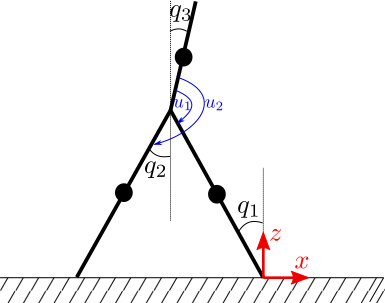

syms u1 u2 delq1 delq2 delq3
th1 = pi + q1 - q3; % angle between link 1 and link 3
%th2 = pi - q2 + q3; % angle between link 2 and link 3
th2 = pi + q2 - q3; % angle between link 2 and link 3
del_th1 = delq1 - delq3; % virtual angle variation for th1
%del_th2 = delq3 - delq2; % virtual angle variation for th2
del_th2 = - delq3 + delq2; % virtual angle variation for th2
del_W1 = u1 * del_th1; % virtual work done by u1
del_W2 = u2 * del_th2; % virtual work done by u2
del_W = del_W1 + del_W2; % total virtual work
del_W = collect(del_W, [delq1, delq2, delq3])

$$del\_W = u_{1}\,{\mathrm{delq}}_{1}+u_{2}\,{\mathrm{delq}}_{2}+\left(-u_{1}-u_{2}\right)\,{\mathrm{delq}}_{3}$$

Extract the B matrix: 

First calculate the right hand side of the equations of motion from the expression of del_W: 

Eq = R_Eq1

Eq2 = R_Eq2 

Eq3 = R_Eq3

Calculate R_Eq1, R_Eq2, R_q3

R_Eq1 = subs(del_W, {delq2, delq3}, {0, 0})/delq1;% use subs function 
R_Eq2 = subs(del_W, {delq1, delq3}, {0, 0})/delq2;
R_Eq3 = subs(del_W, {delq1, delq2}, {0, 0})/delq3;

From the equations above write the $B$ matrix:

B(1, 1) = subs(R_Eq1, u2, 0)/u1;
B(1, 2) = subs(R_Eq1, u1, 0)/u2;
B(2, 1) = subs(R_Eq2, u2, 0)/u1;
B(2, 2) = subs(R_Eq2, u1, 0)/u2;
B(3, 1) = subs(R_Eq3, u2, 0)/u1;
B(3, 2) = subs(R_Eq3, u1, 0)/u2;
B = sym(B) % why do we need this line of code? 

$$B = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -1 & -1 \end{array}\right)$$

Write the symbolic functions to a MATLAB *.m function. 

**Note: After running this section, you must modify the functions eval_M, eval_C, eval_G to have the following signature:**

function M = eval_M(q)

function C  = eval_C(q, dq)

function G = eval_G(q)

function B = eval_B()

matlabFunction(M, 'File', '../dynamics/eval_M');
matlabFunction(C, 'File', '../dynamics/eval_C');
matlabFunction(G, 'File', '../dynamics/eval_G');
matlabFunction(B, 'File', '../dynamics/eval_B');

**Finally, remove the temporary functions eval_M_tmp, eval_C_tmp, eval_G_tmp, eval_B_tmp. We later, will be using the functions eval_M.m, eval_C.m, eval_G.m, eval_B.m.**

## Test your functions: 

To run the test function (in the 'test' folder) you should add some folders to the path. Make sure that your are in the generate_model folder and then run the following code:

addpath('../set_parameters', '../dynamics', '../test');